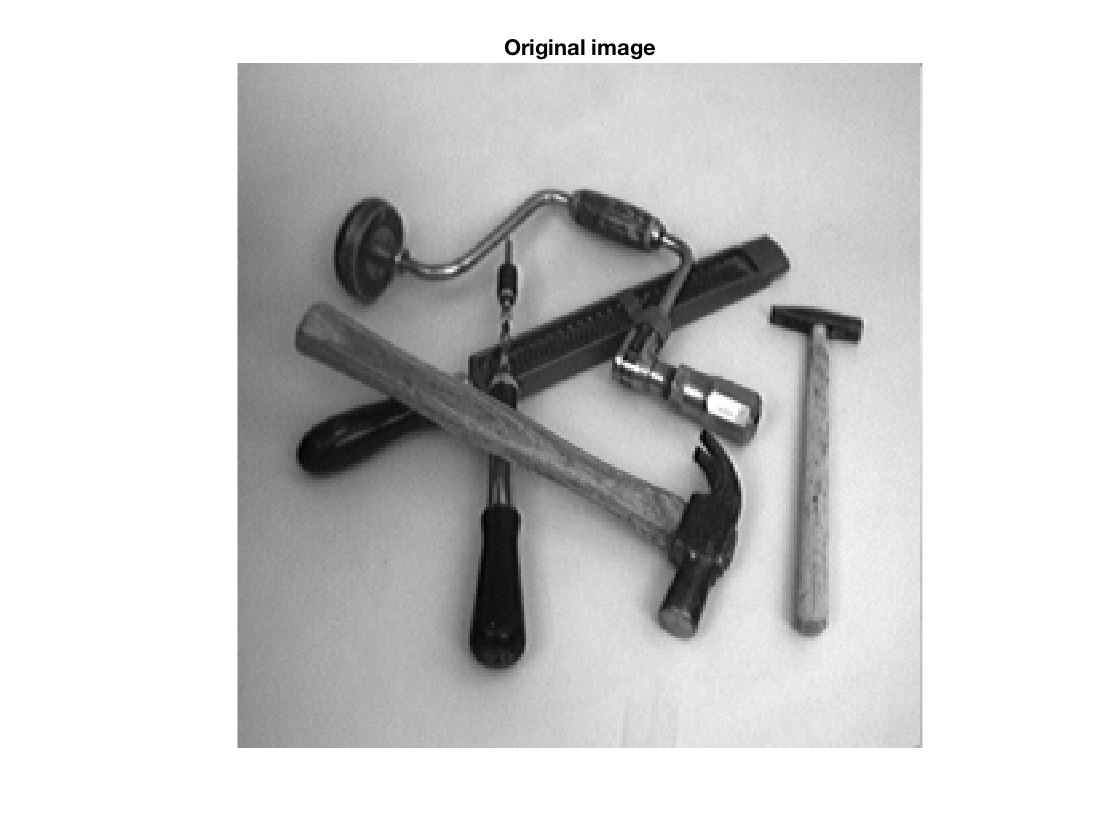

% Q1
tools = few256;
showgrey(tools);
title("Original image");

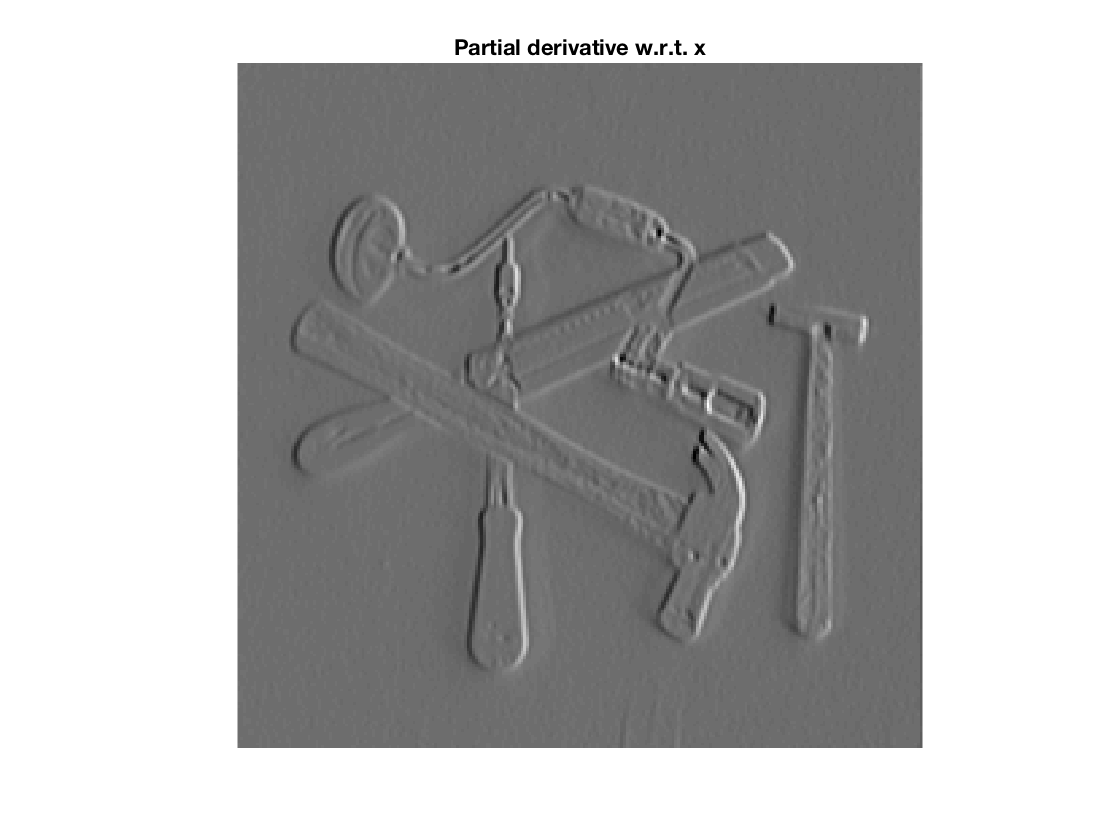


% Sobel (taking flip into account)
deltay = [1 2 1; 0 0 0; -1 -2 -1];
deltax = deltay';

dxtools = conv2(tools, deltax, 'valid');
dytools = conv2(tools, deltay, 'valid');

showgrey(dxtools);
title("Partial derivative w.r.t. x");

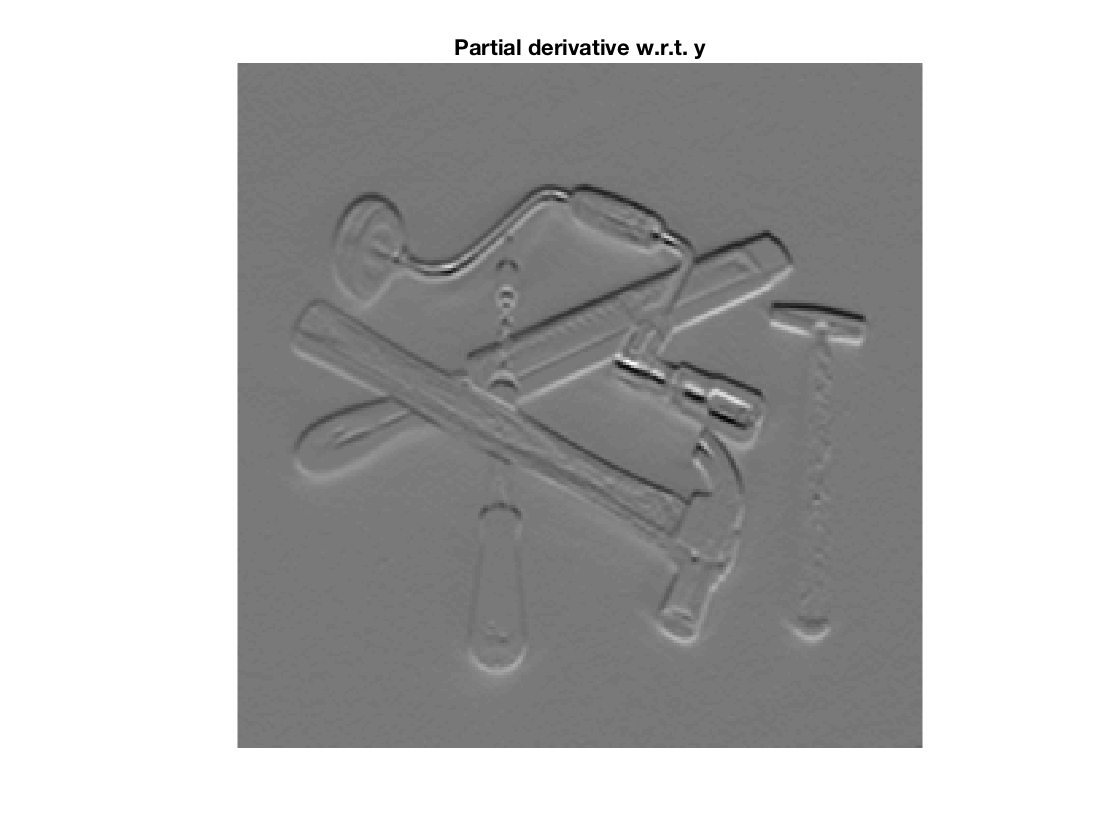


showgrey(dytools);
title("Partial derivative w.r.t. y");


display(size(tools));

   256   256



display(size(dxtools));

   254   254



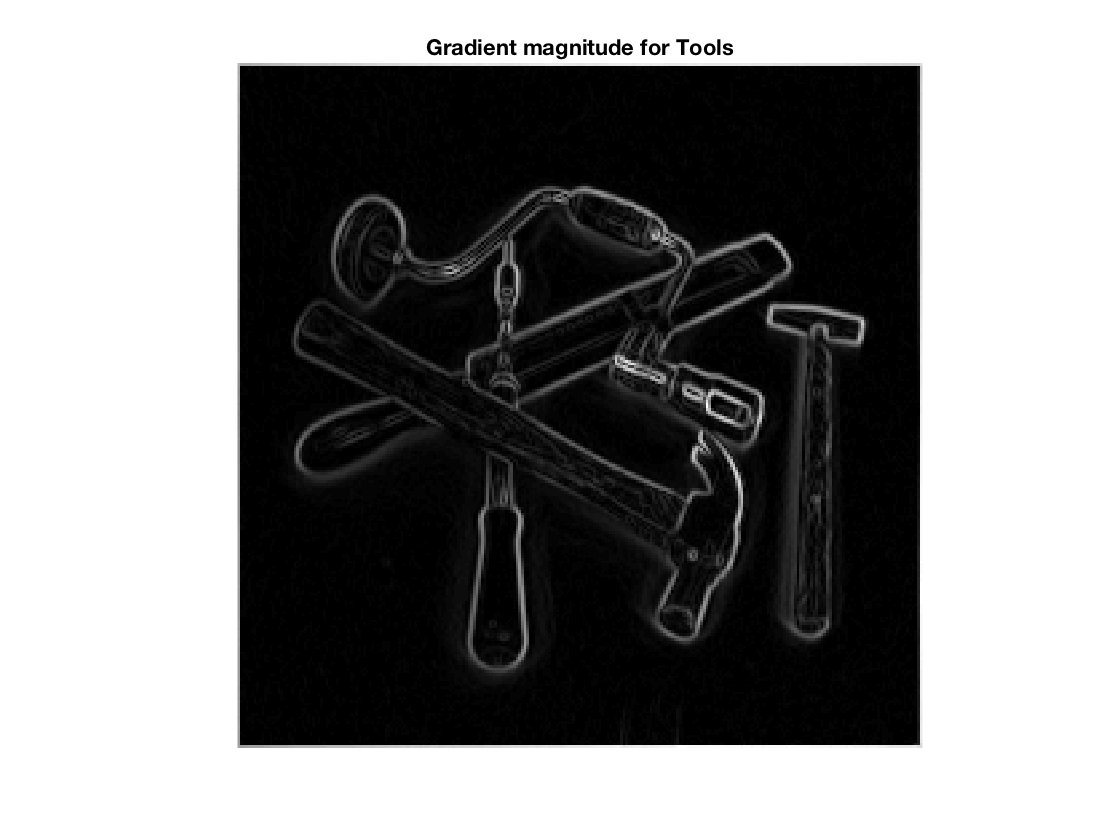

% Q2
house = godthem256;

gradmagntools = sqrt(Lv(tools));
showgrey(gradmagntools);
title("Gradient magnitude for Tools");

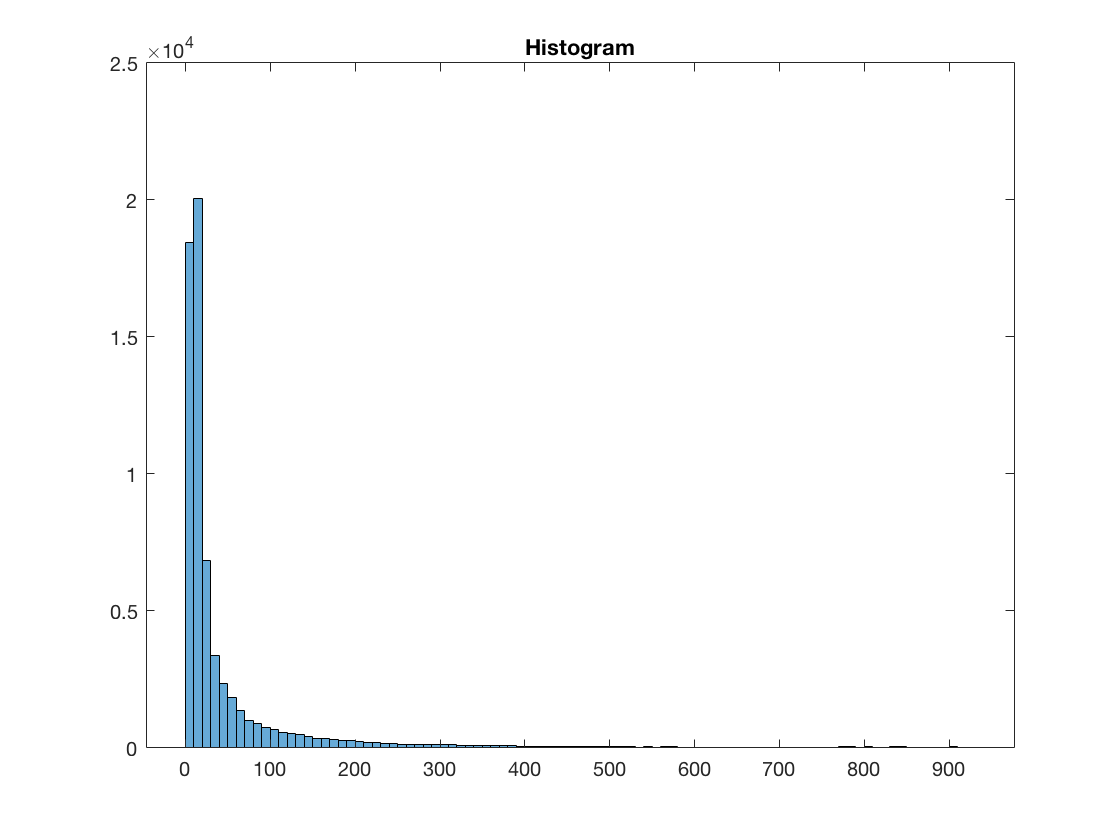

histogram(gradmagntools)
title("Histogram");

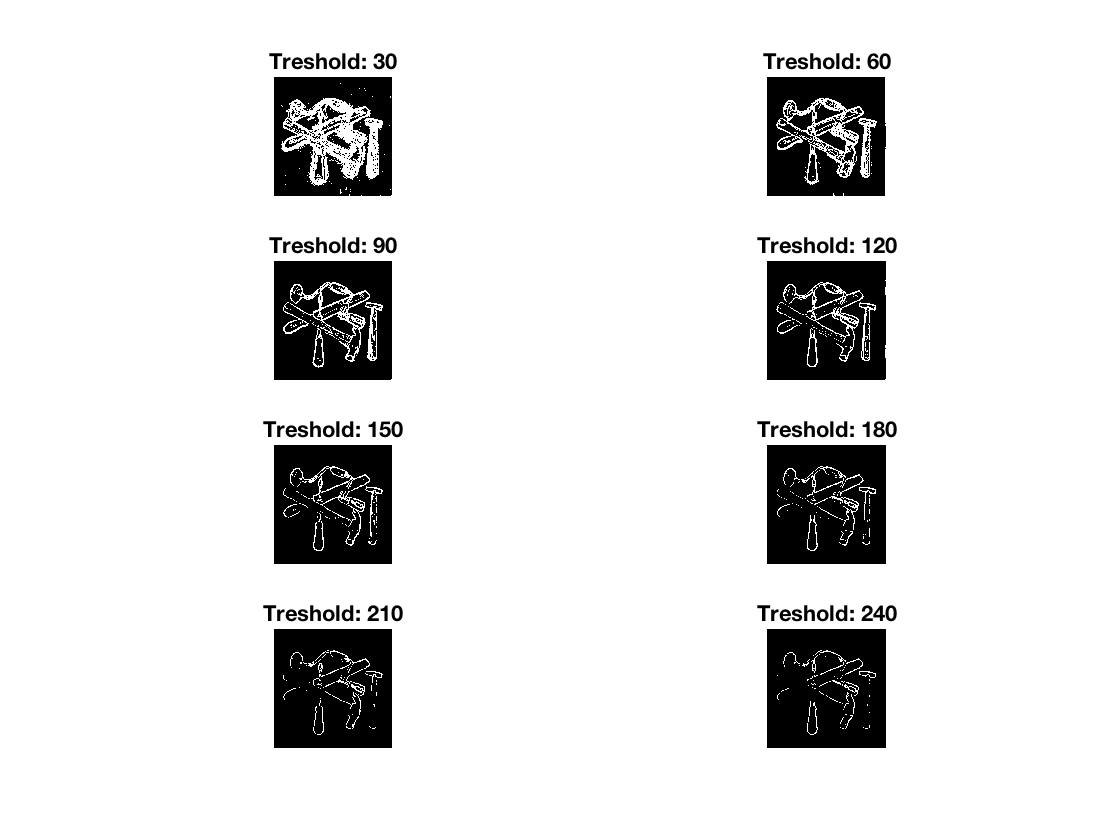


for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagntools - thresh) > 0);
    title(sprintf("Treshold: %d", thresh));
end

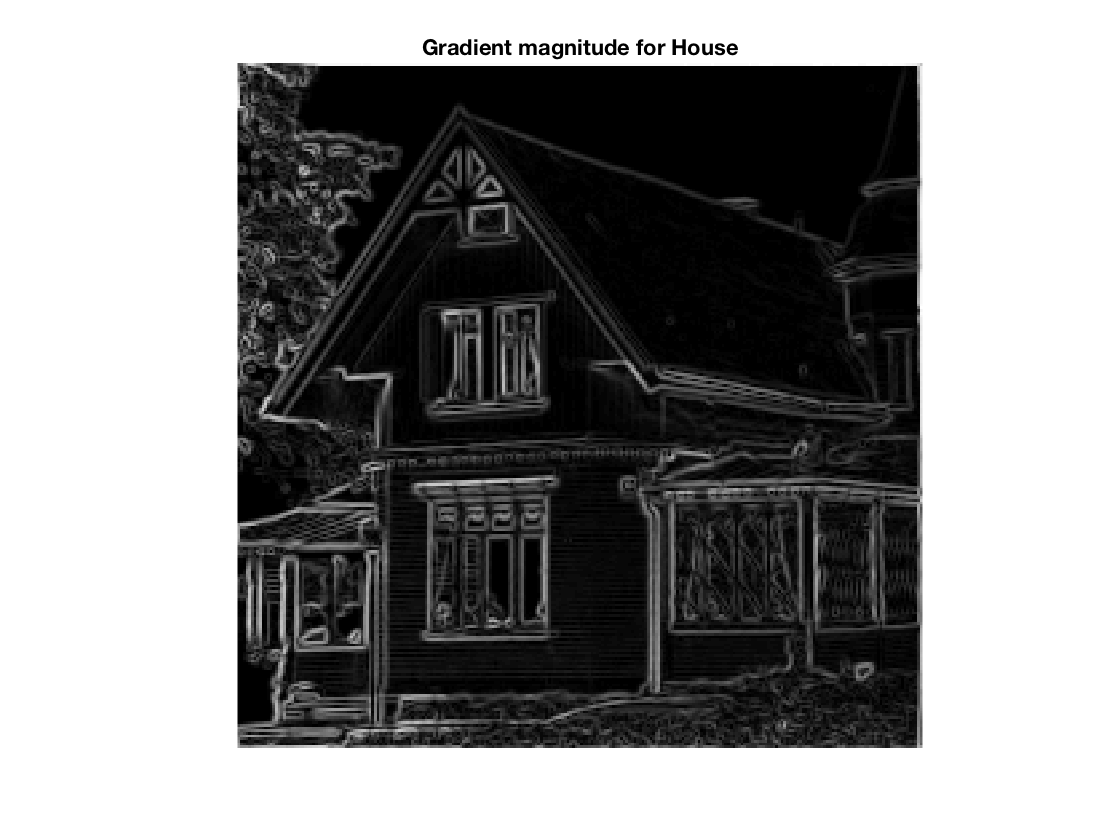

close all

gradmagnhouse = sqrt(Lv(house));
showgrey(gradmagnhouse);
title("Gradient magnitude for House");

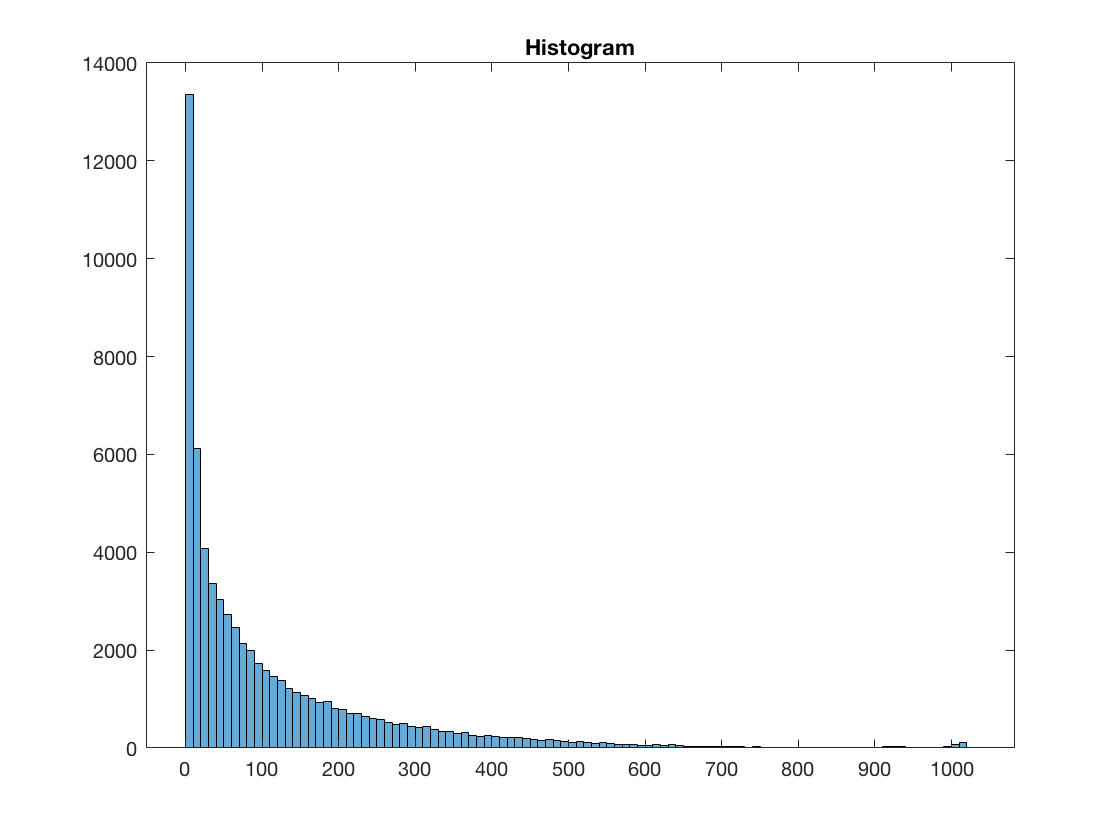

histogram(gradmagnhouse)
title("Histogram");

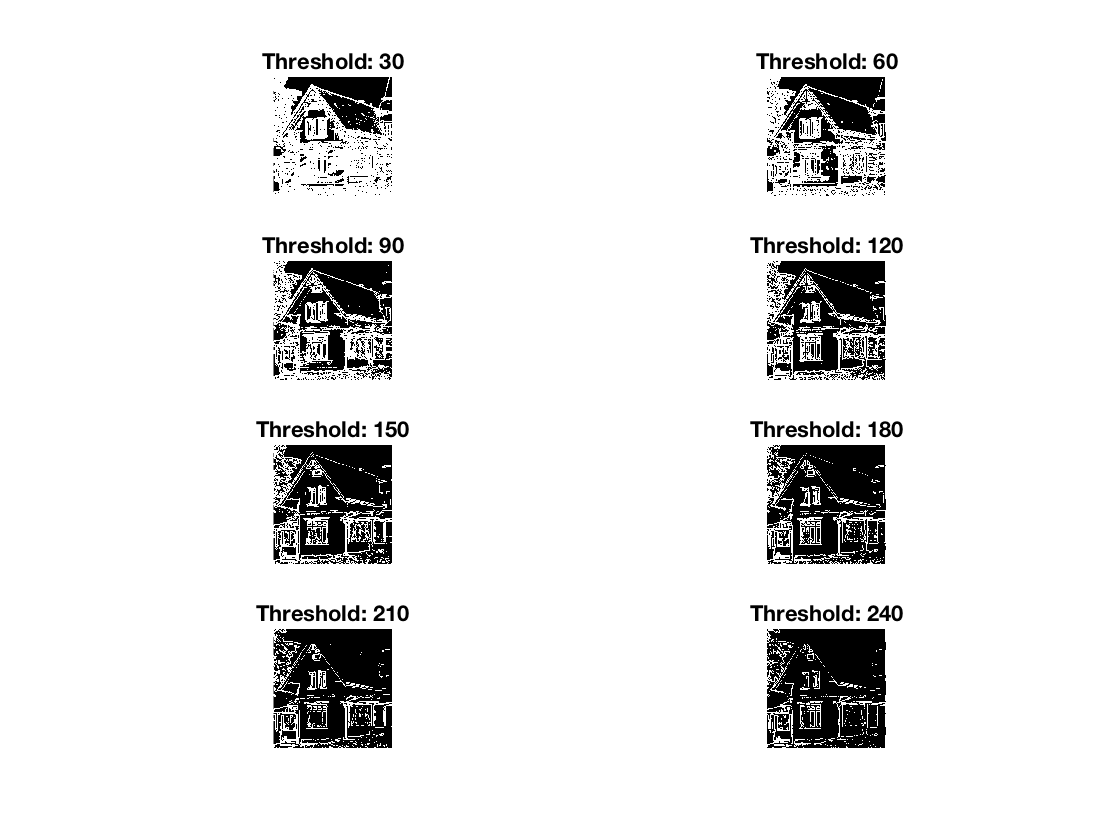


for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagnhouse - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

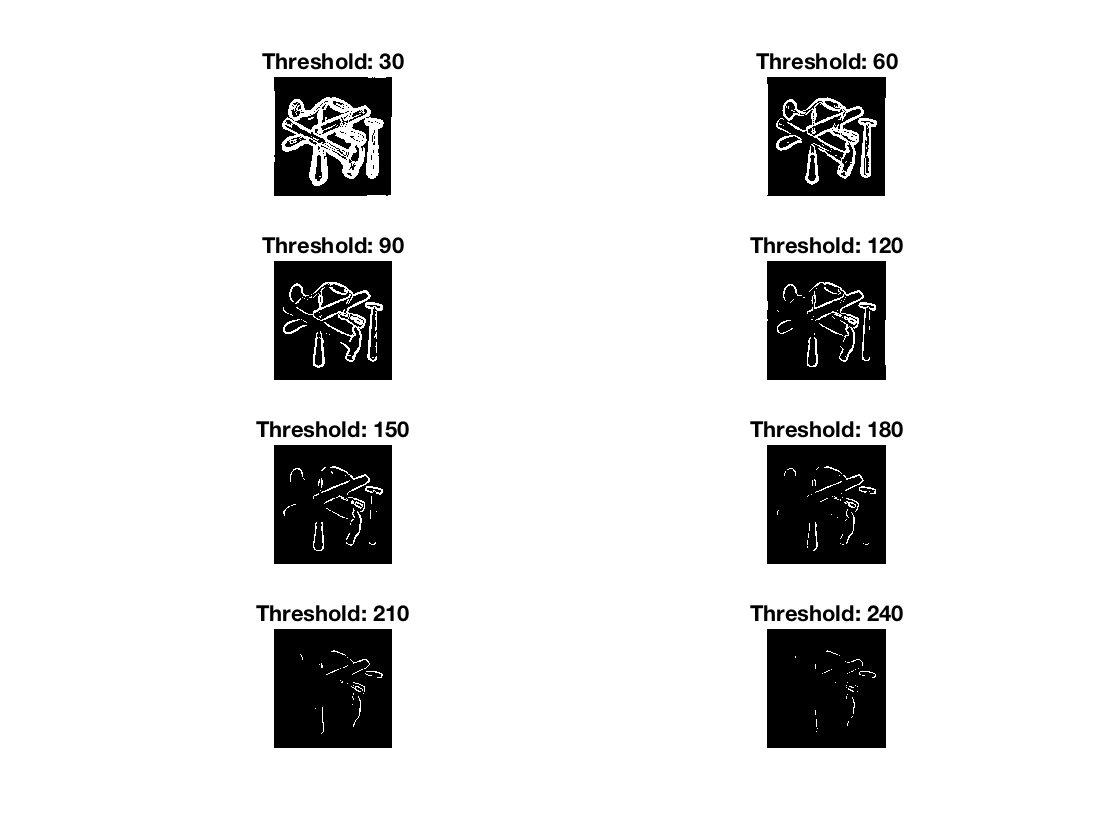

% Q3
close all
tools_smoothed = gaussfft(tools, 2);
% showgrey(tools);
% showgrey(tools_smoothed);
gradmagntools_smoothed = sqrt(Lv(tools_smoothed));
for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagntools_smoothed - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

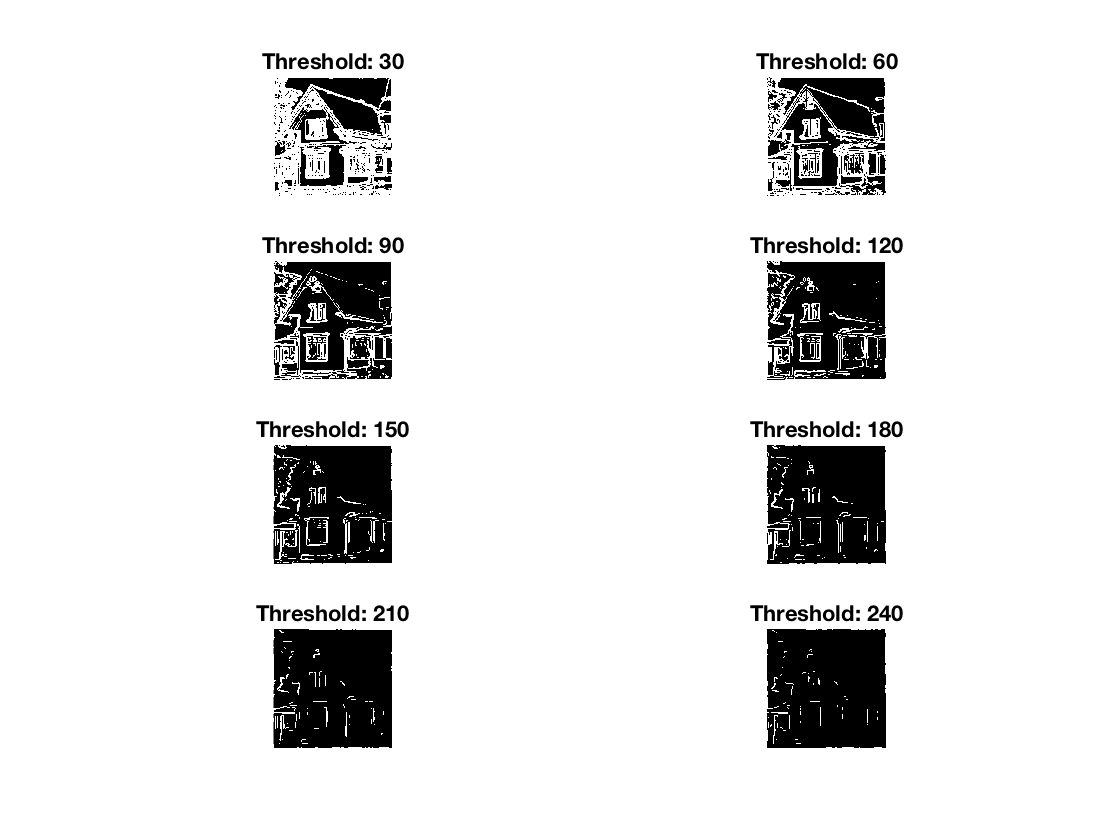

close all
house_smoothed = gaussfft(house, 2);
% showgrey(house);
% showgrey(house_smoothed);
gradmagnhouse_smoothed = sqrt(Lv(house_smoothed));
for i = 1:8
    subplot(4,2,i);
    thresh = i * 30;
    showgrey((gradmagnhouse_smoothed - thresh) > 0);
    title(sprintf("Threshold: %d", thresh));
end

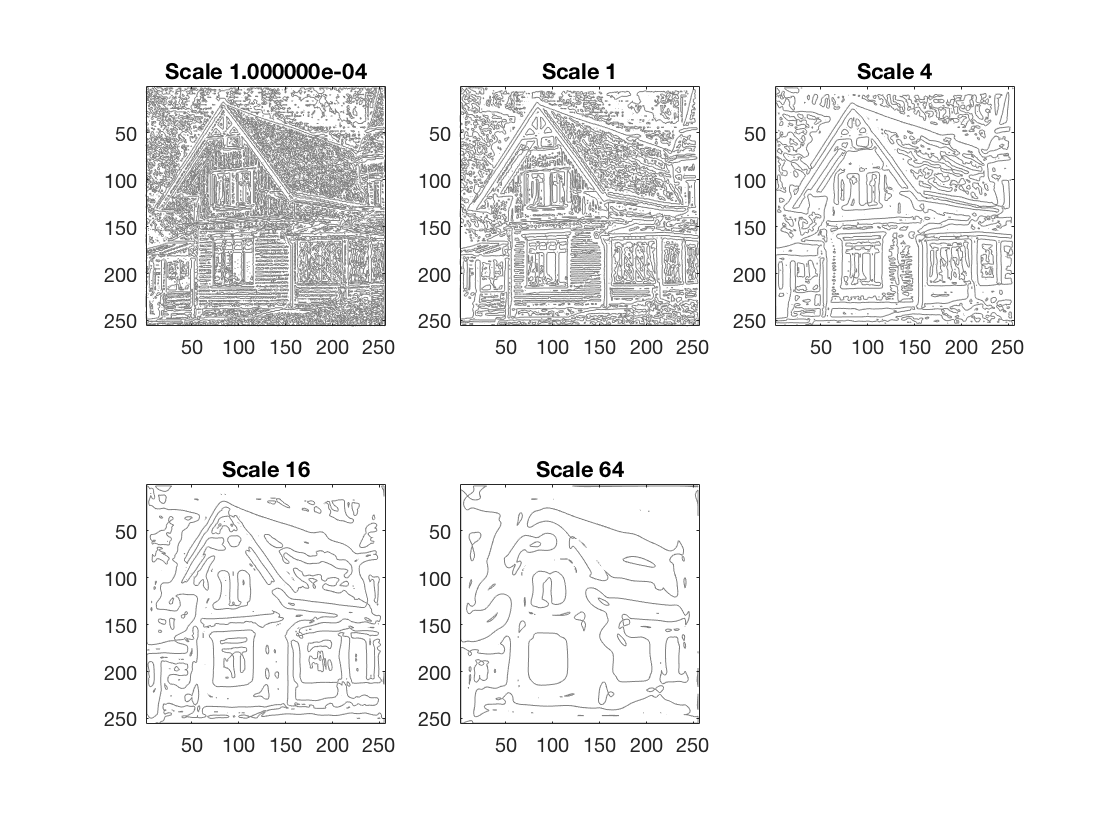

house = godthem256;
% contour(Lvvtilde(discgaussfft(house, 4.0), 'same'), [0 0])
% axis('image')
% axis('ij')

scales = [0.0001 1.0 4.0 16.0 64.0];
for i = 1:5
    subplot(2,3,i);
    contour(Lvvtilde(discgaussfft(house, scales(i)), 'same'), [0 0])
    axis('image')
    axis('ij')
    title(sprintf("Scale %d", scales(i)));
end

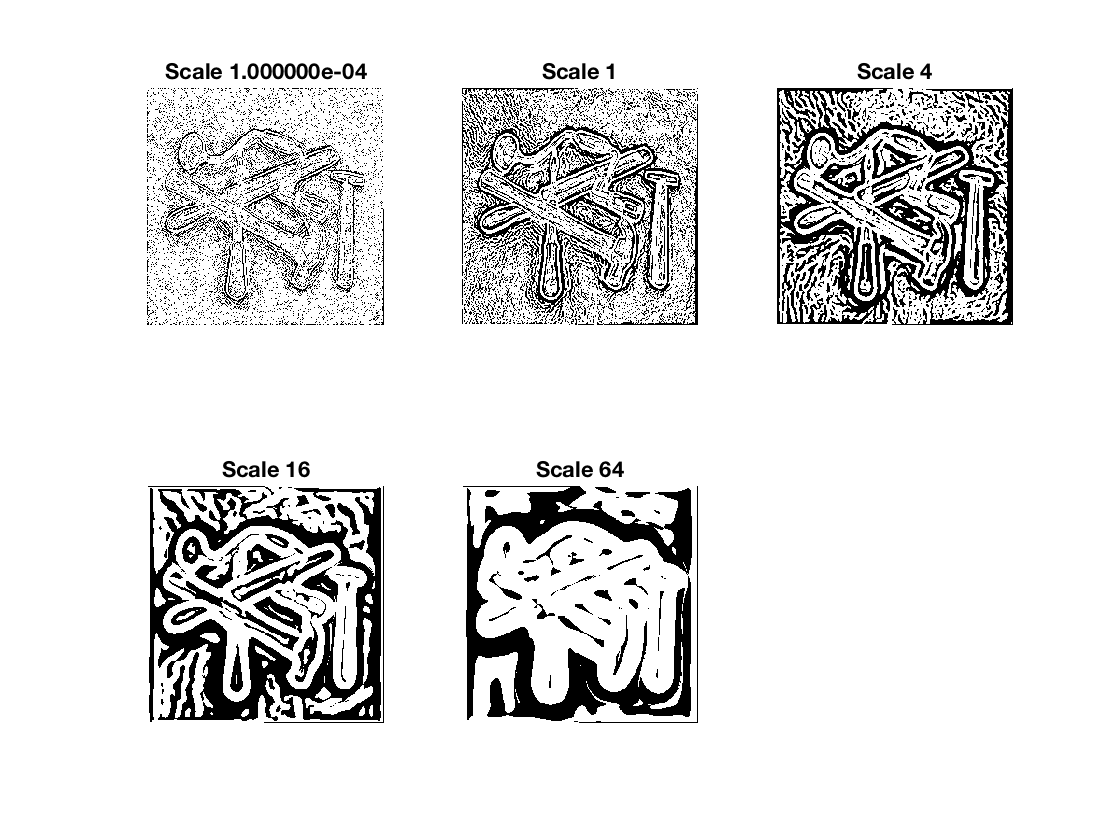

close all
tools = few256;
scales = [0.0001 1.0 4.0 16.0 64.0];
for i = 1:5
    subplot(2,3,i);
    showgrey(Lvvvtilde(discgaussfft(tools, scales(i)), 'same') < 0)
    title(sprintf("Scale %d", scales(i)));
end

% close all
% house = godthem256;
% scales = [0.0001 1.0 4.0 16.0 64.0];
% thresholds = [0 20 40 60 80];
% for i = 1:5
%     for j = 1:5
%         curves = extractedge(house, scales(i), thresholds(j), 'same');
%         subplot(5,5,(i-1)*5 + j);
%         overlaycurves(house, curves)
%         title(sprintf("Scale %d, thresh %d", scales(i), thresholds(j)));
%     end
% end

% 


close all
curves = extractedge(house, 3.0, 35, 'same');

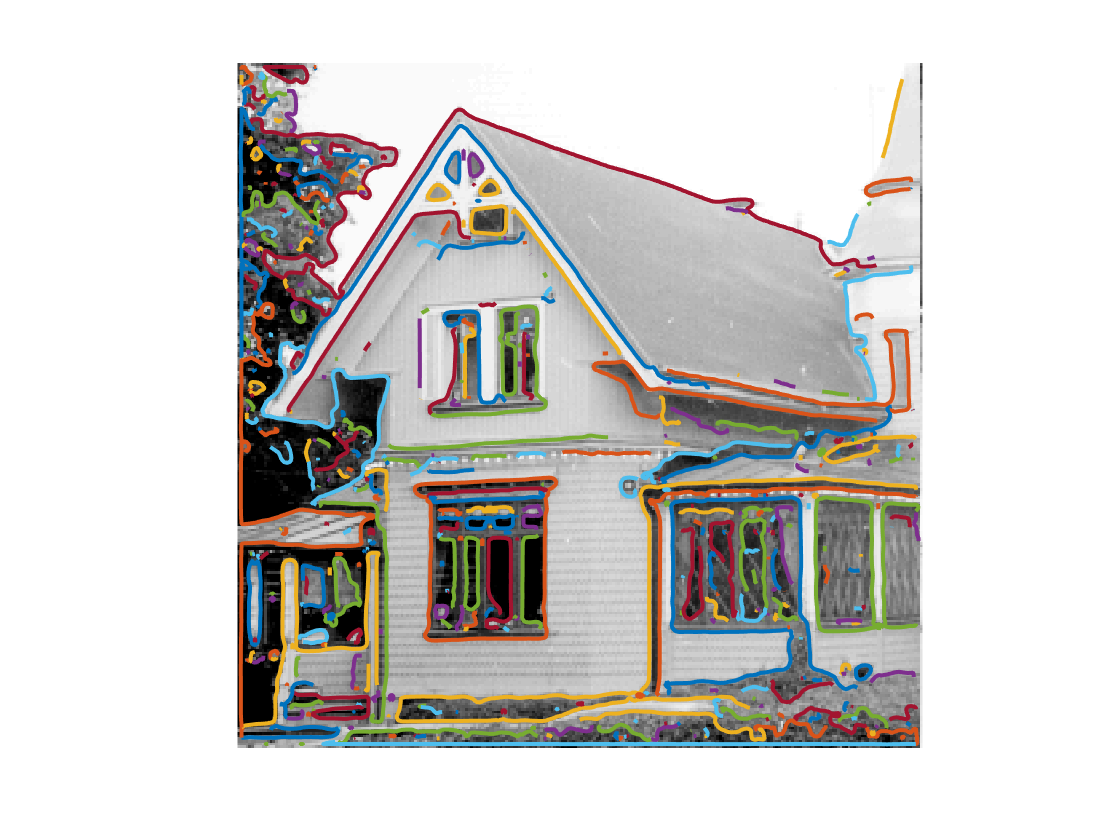

overlaycurves_fat(house, curves)

tools = few256;
curves = extractedge(tools, 4.0, 45, 'same');

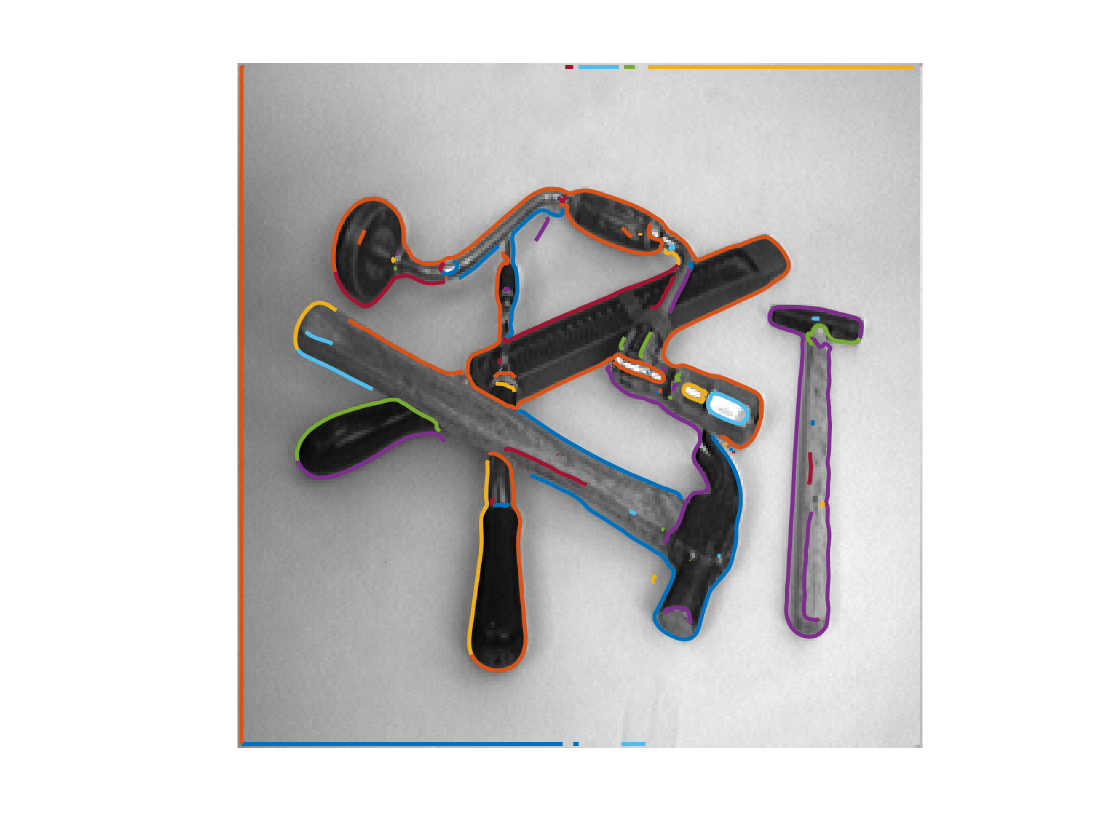

overlaycurves_fat(tools, curves)

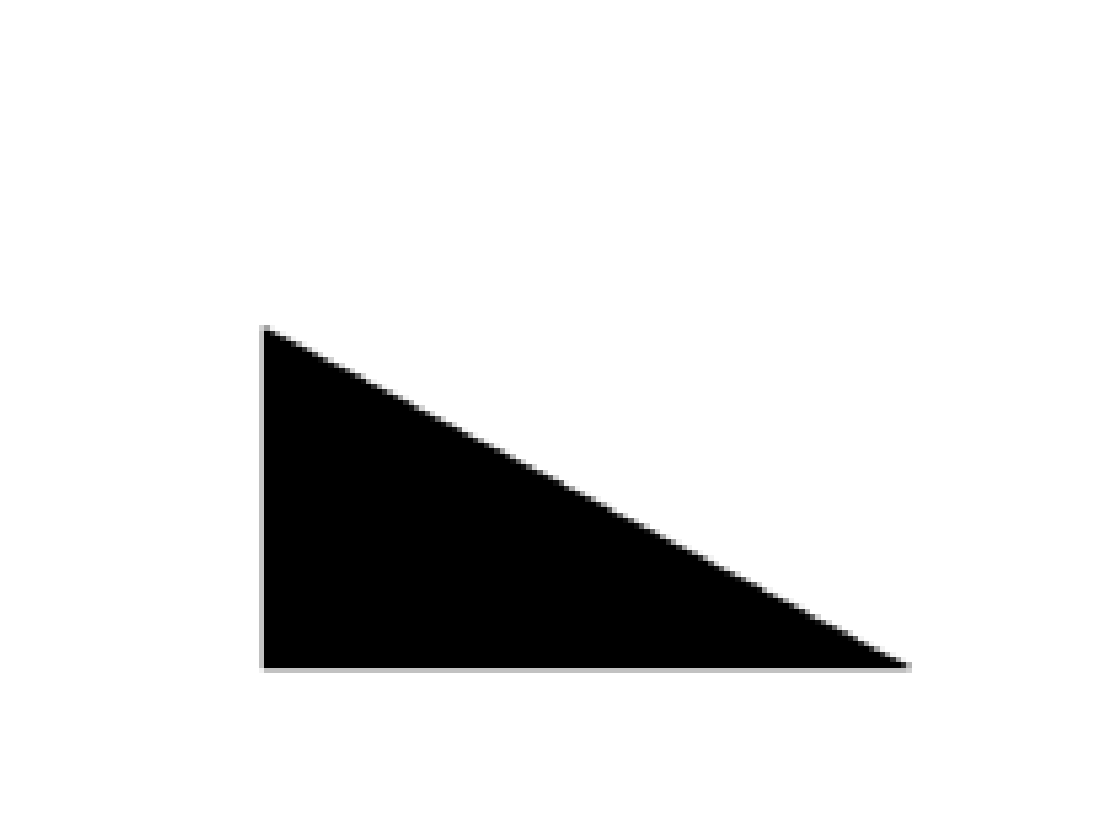

testimage1 = triangle128;
% smalltest1 = binsubsample(testimage1);
showgrey(testimage1);

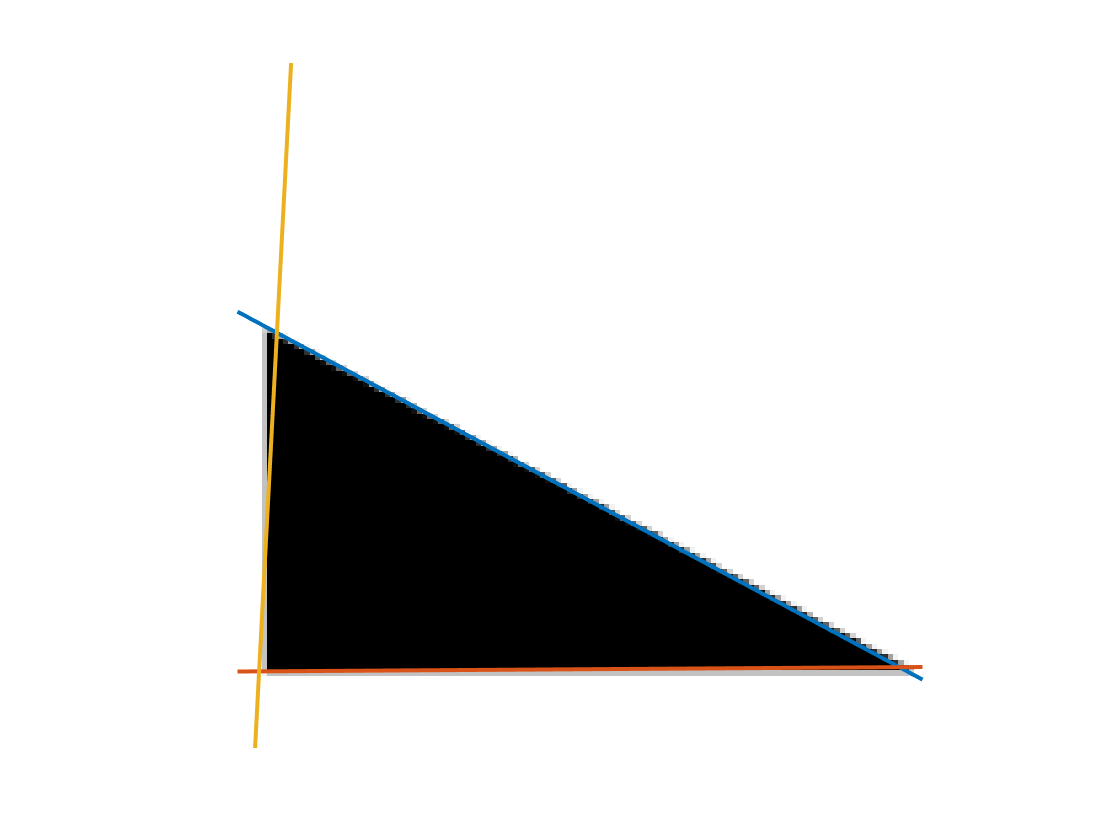

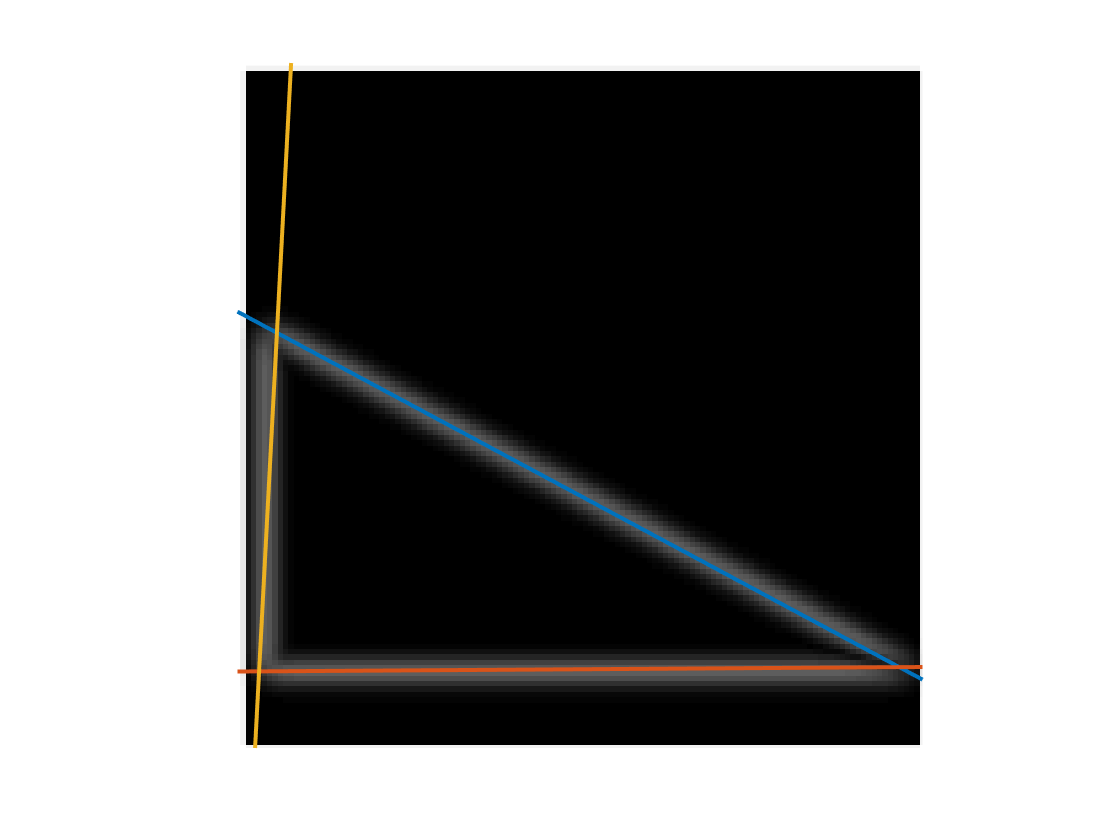

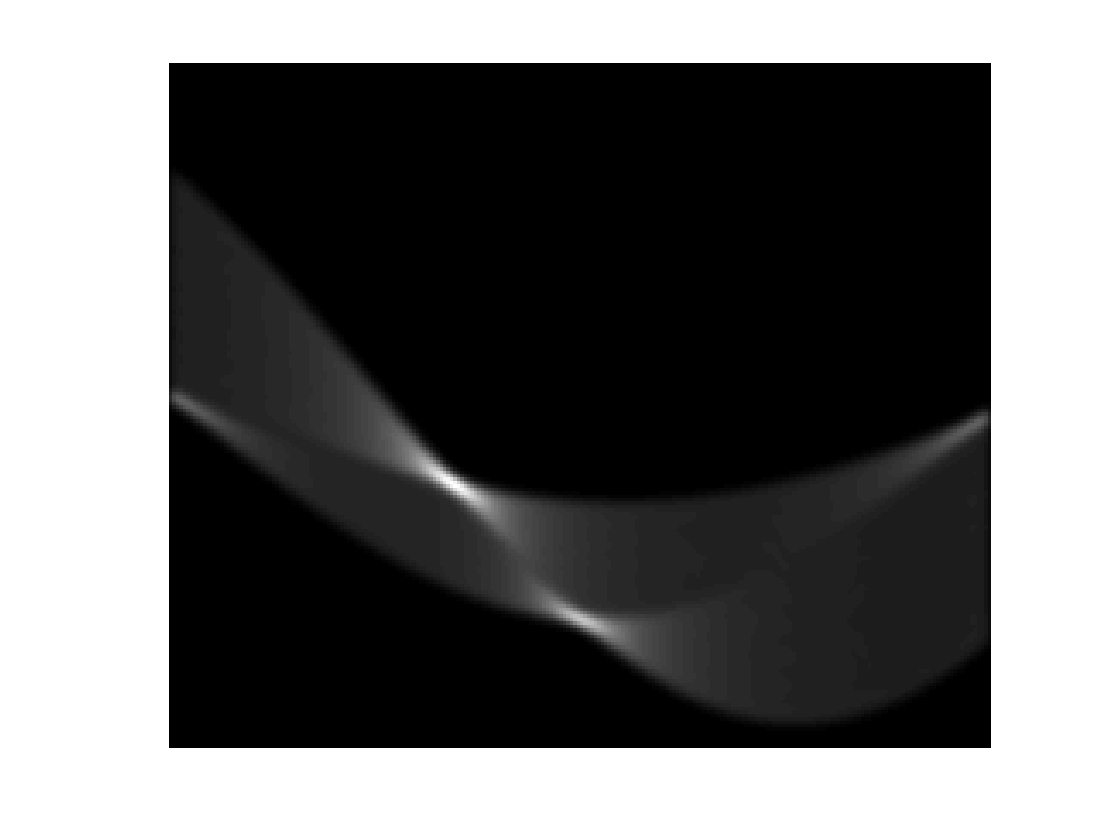

[linepar, acc] = houghedgeline(testimage1, 4.0, 40, 200, 240, 3, 2);


disp(linepar)

   40.9340   -0.4929
  113.7056    0.0066
   10.0061    1.5182



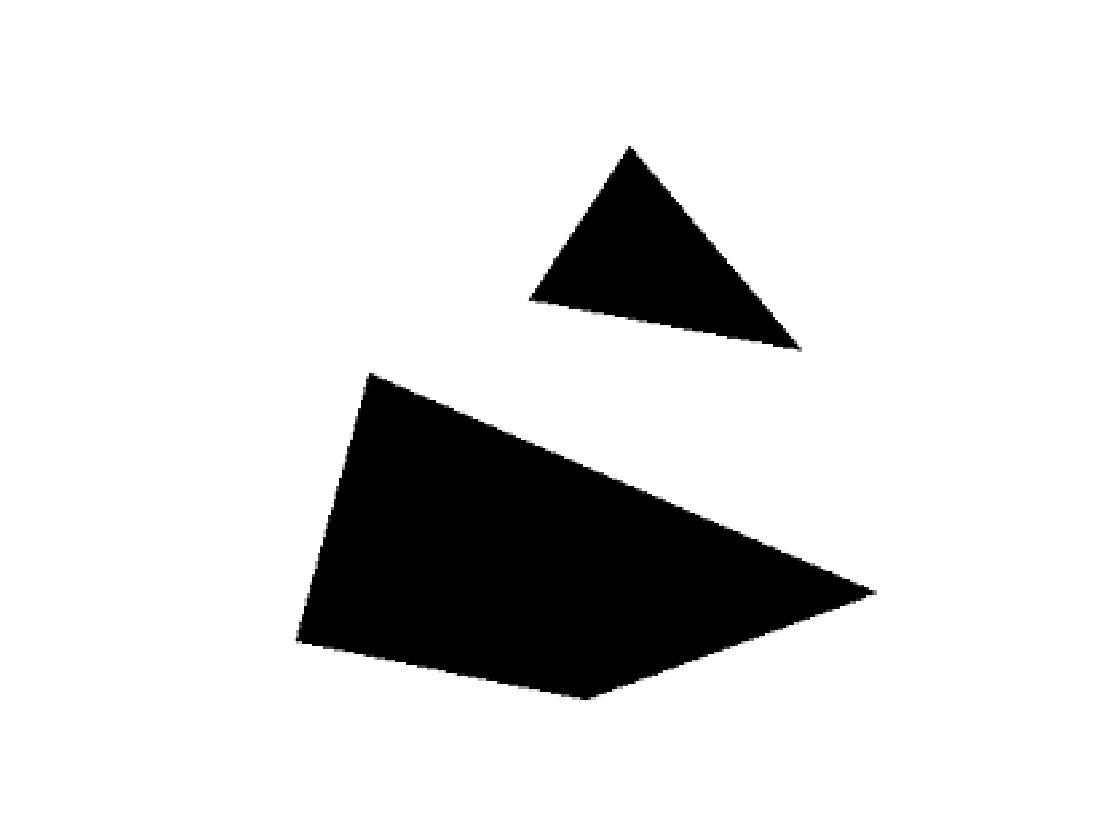

testimage2 = houghtest256;
showgrey(testimage2);

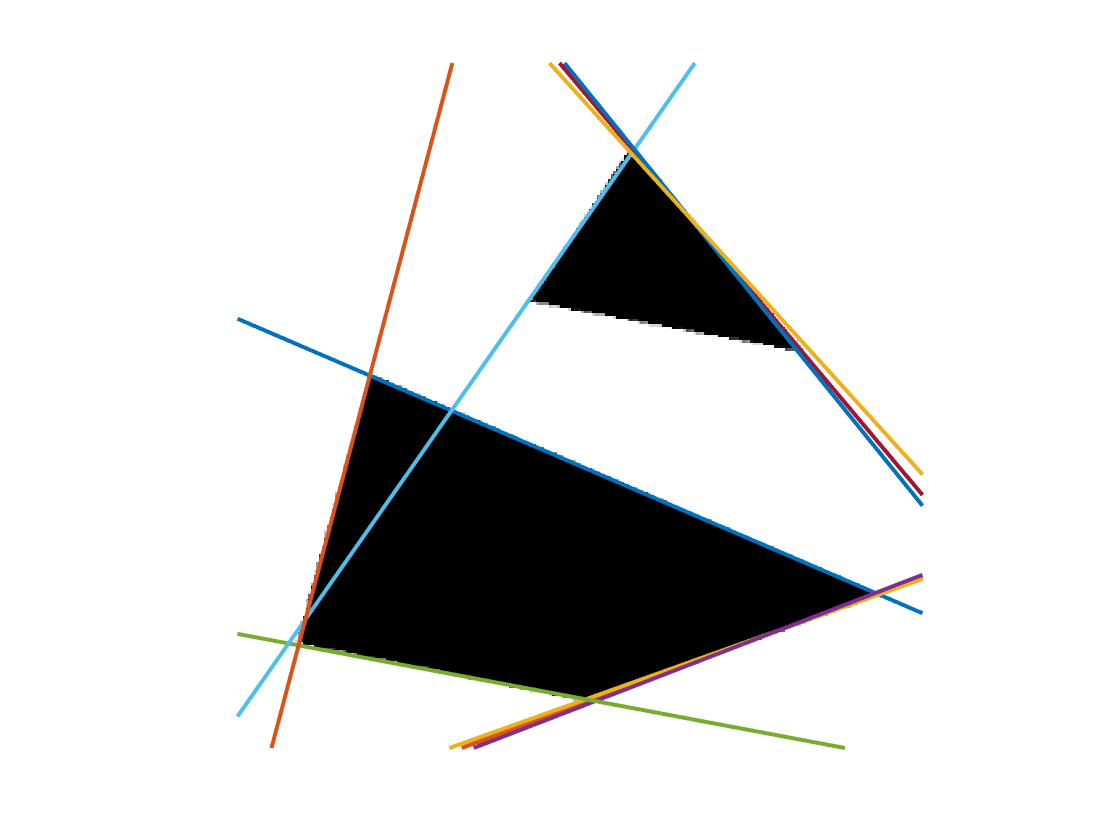

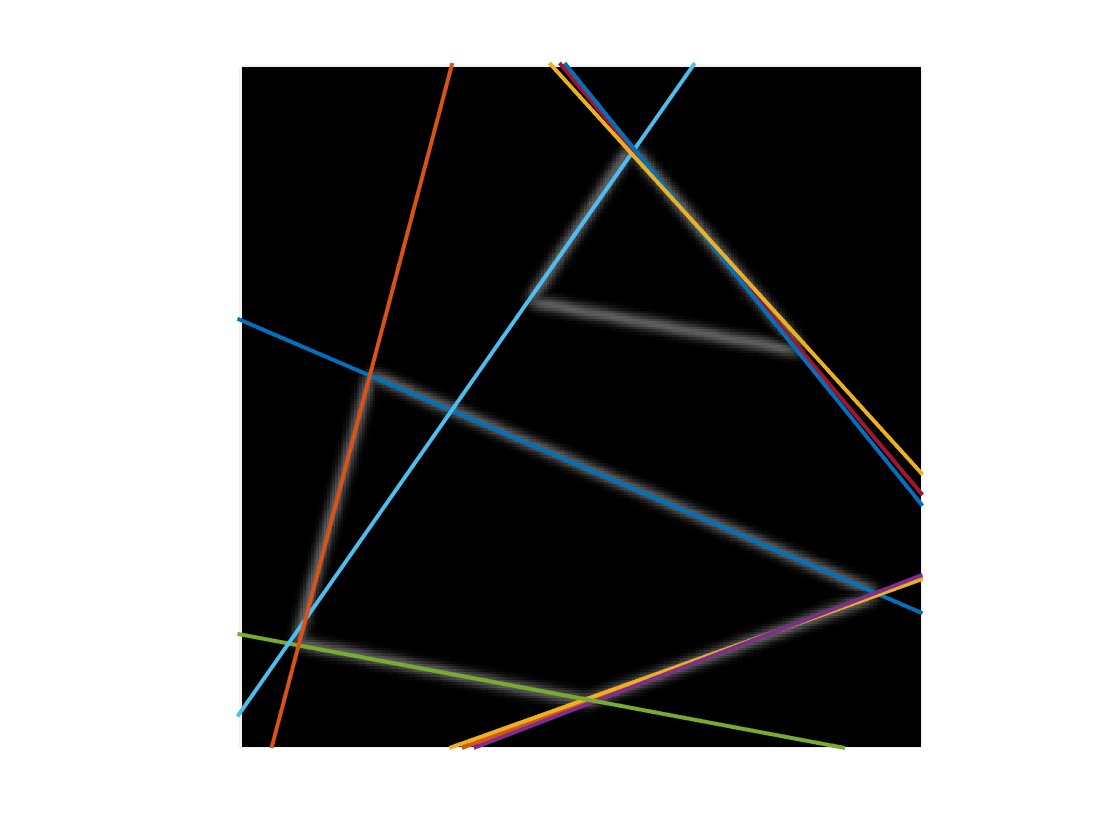

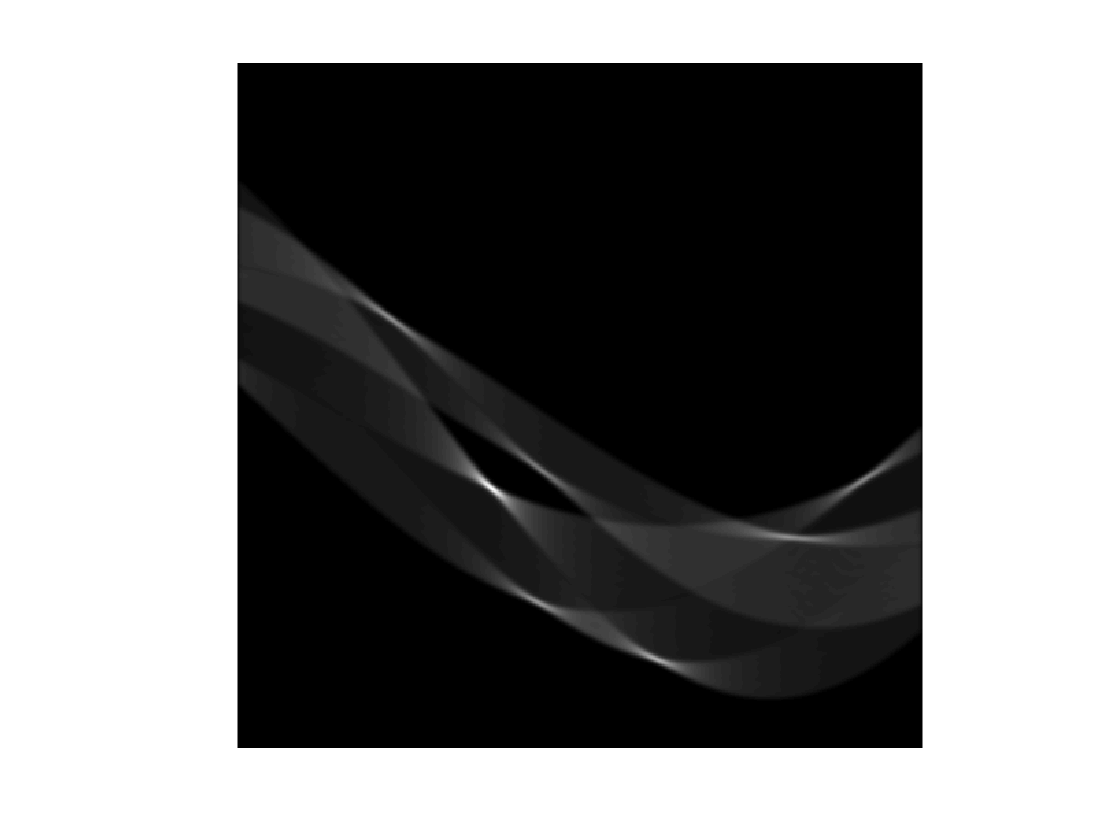

% smalltest2 = binsubsample(binsubsample(testimage2));
% showgrey(smalltest2);
[linepar, acc] = houghedgeline(testimage2, 4.0, 10, 500, 500, 10, 2); 

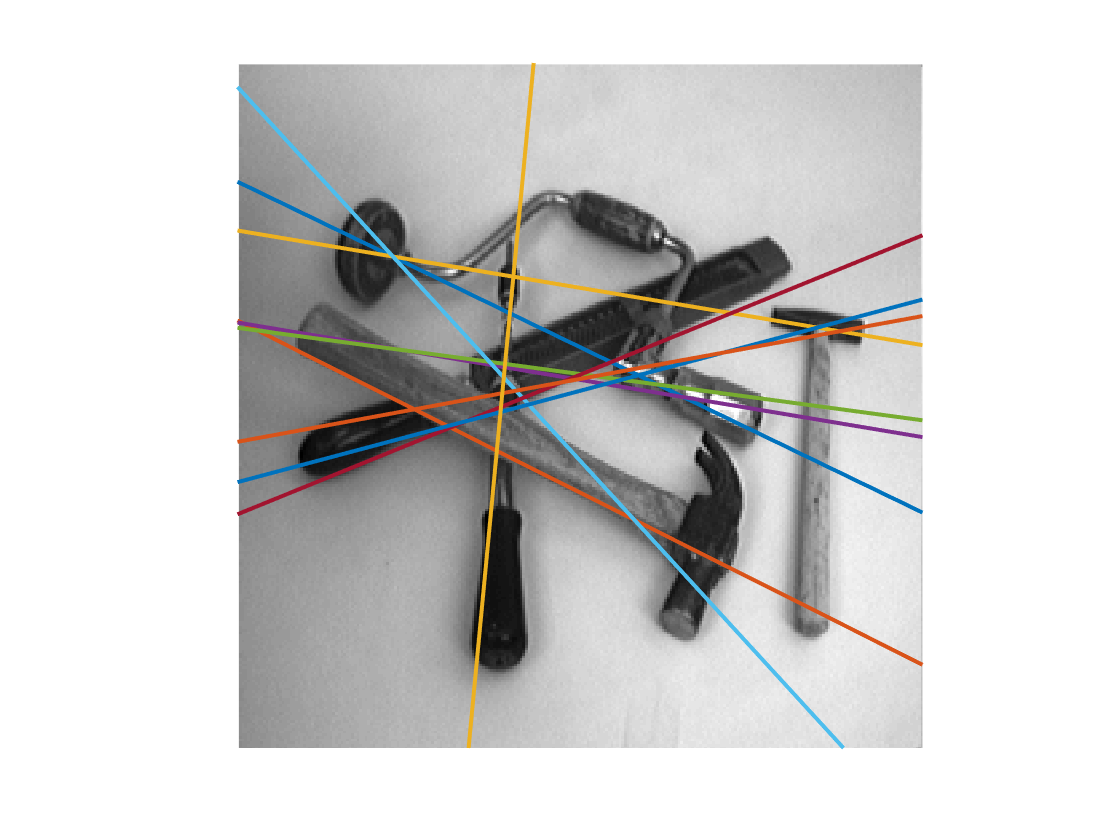

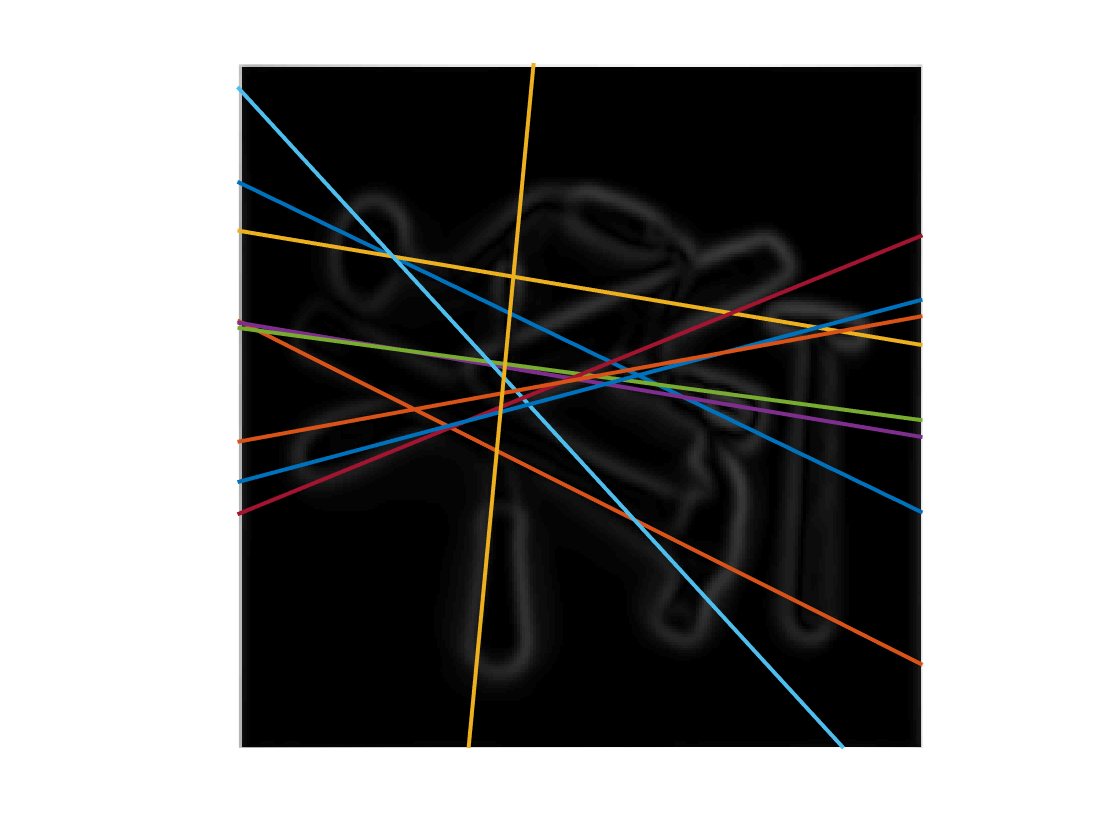

tools = few256;
[linepar, acc] = houghedgeline(tools, 6.0, 20, 300, 200, 10, 2);

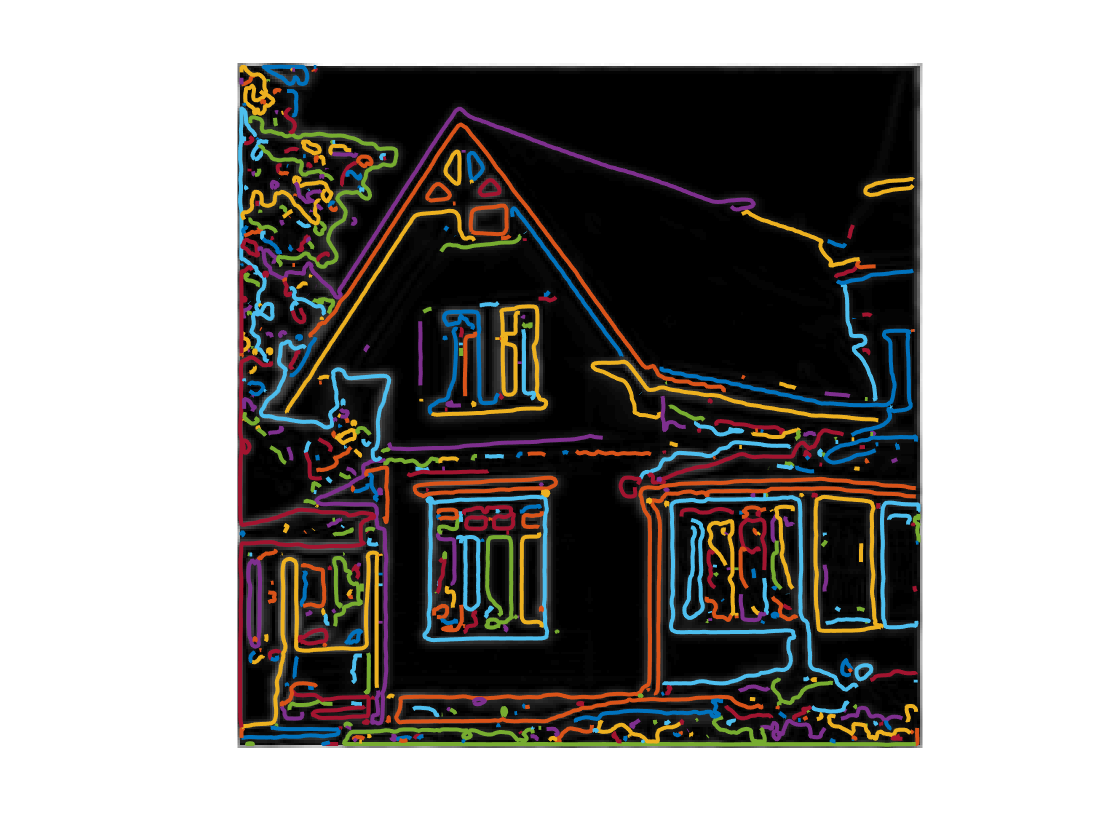

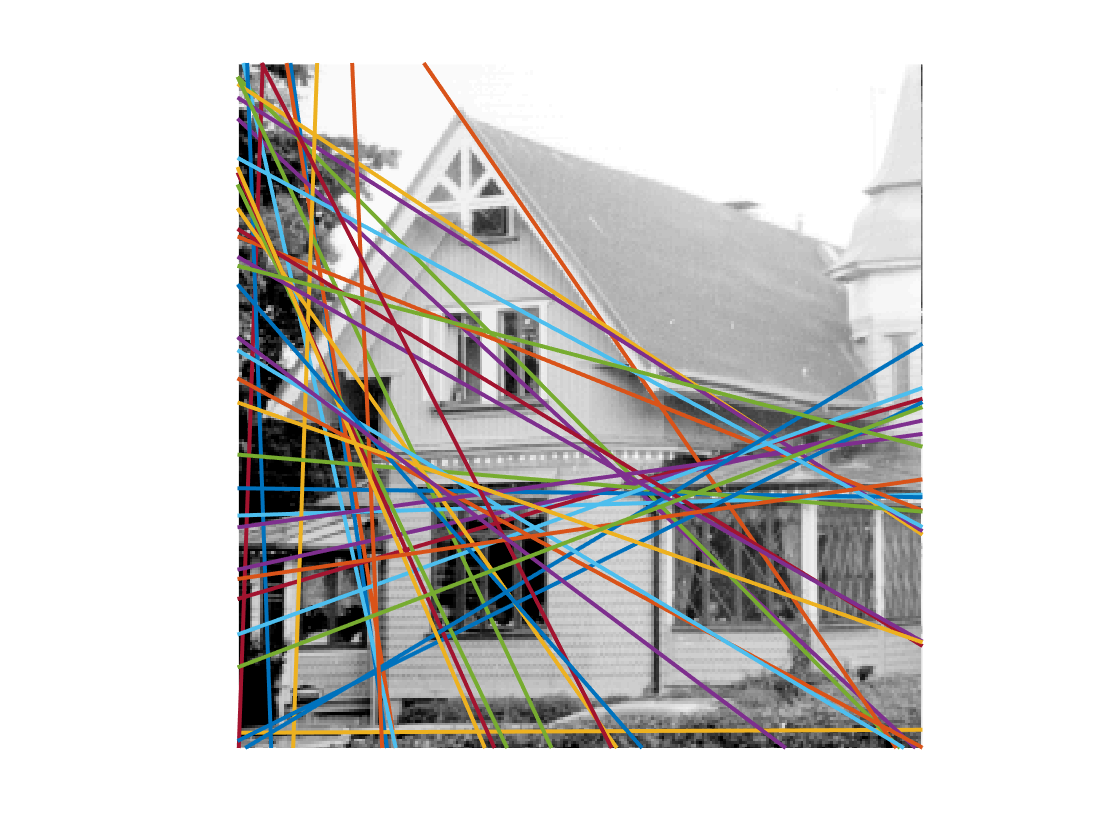

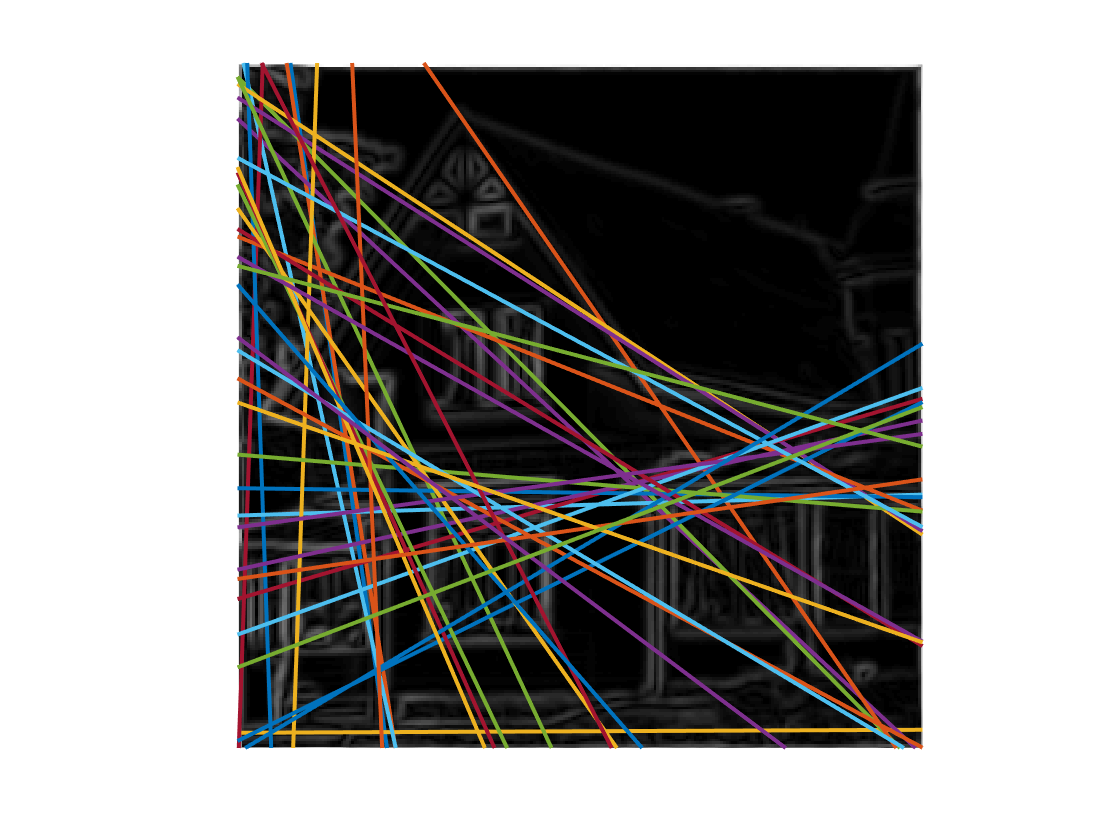

house = godthem256;
[linepar, acc] = houghedgeline(house, 2.0, 50, 500, 360, 40, 3); 